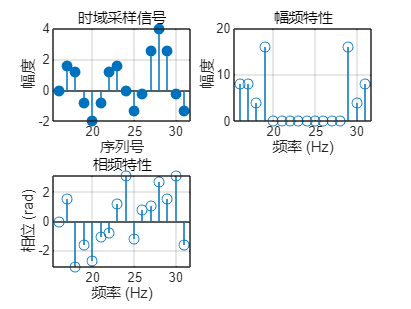

clear;clc;
f = 50;  % 基波频率
A = [0.5, 1, 0.5, 2];  % 振幅
phi = [0, pi/2, pi, -pi/2];  % 相位
N = 16;  % 采样频率倍数
L = 2 * N;  % 采样点数
fs = N * f;  % 采样频率
T = 1 / fs;  % 采样间隔
t = (0:L-1) * T;  % 采样时间
s = zeros(size(t));  % 初始化采样信号
for k = 1:length(A)
    sk = A(k) * cos(2 * pi * (k-1) * f * t + phi(k));
    s = s + sk;
end
% DFT计算
X = fft(s(17:32));  % 取第二个周期进行DFT计算
n=16:31;%序列号
% 离散时域波形图
figure;
subplot(2,2,1);
stem(n, s(17:32), 'filled');  % 使用序列号绘制离散时域波形
xlabel('序列号');
ylabel('幅度');
title('时域采样信号');
grid on;
% 幅频特性图
subplot(2,2,2);
stem(n, abs(X));
xlabel('频率 (Hz)');
ylabel('幅度');
title('幅频特性');
grid on;
% 相频特性图
subplot(2,2,3);
stem(n, angle(X));
xlabel('频率 (Hz)');
ylabel('相位 (rad)');
title('相频特性');
grid on;